# **LAB:  Bearing Fault Monitoring and RUL Estimation**

**Name: HanMinung   **

**Due in 1 week**

## **Instruction**

In this LAB, you are required to create a simple code for Fault Monitoring and RUL estimation

You can refer to RUL estimation tutorial codes and related papers

**Fault Monitoring**

- Detect Fault Status

- Display WARNING MESSAGE

**RUL Estimation **

- Estimate RUL similar to Tutorial codes

- The end of Life can be assumed when the repair is done

## Dataset

Raw Dataset of Bearing Velocity measured that shows a Bearing Life cycle before the repair is done. Also the velocity measurement after the repair is provided.

**Download** bearing  dataset for this lab: [[Download here](https://drive.google.com/file/d/1L9iz34MI8v469J30SCM6_38TT7TICXrX/view?usp=share_link)]

Using the given dataset, develop simple program for

- Bearing velocity measured 24 times per day

- Each measurement is L=8192 with Fs=2560Hz  

- Measurement for consecutive days until repair is done

- 24 times per day & 87 days : about 2104 columns

First visualize the vibration signals in the time domain. 

clear

addpath('../Assignment_3_Bearingdata');
addpath('Functions');

load('bearing-vel-fulldata-rul.mat');

% ----------------- Data strcuture -------------------------
% rows: vel measurements / cols: measurement time 
% before repair : 59 days
% after repair : 28 days
% ----------------------------------------------------------

idxRepair = 1431;

bearing = bearingFulldata(:,1:idxRepair);               % before repair
bearingNew = bearingFulldata(:,idxRepair + 1 : end);    % after repair

% Data Length for each measurement
% L=8192
L = length(bearing(:,1));
fs = 2560;                        % sampling frequency [Hz]
ts = 1/fs;                        % sampling time
t = 0:ts:ts*(L-1);

% Day(time) unit upto repair
dataN = length(bearing(1, :));
d = (0:1:dataN)/24;

Plotting bearing velocity raw data

- Initial state:  Day=0 

- Just before repair:  Day=59

- After repair:  Day=60

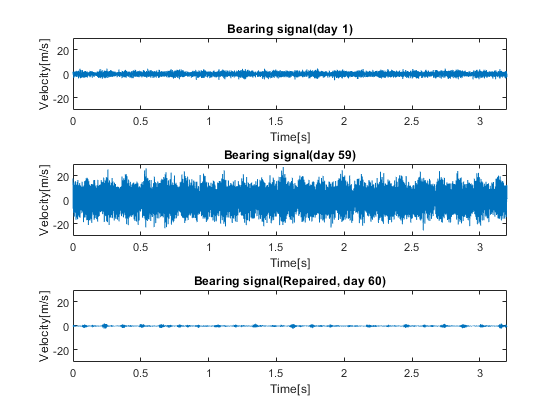

idx1 = 1;    idx2 = idxRepair;    idx3 = 1;

figure
subplot(3, 1, 1);       plot(t, bearing(:, idx1));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 1)');

subplot(3, 1, 2);       plot(t, bearing(:, idx2));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 59)');

subplot(3, 1, 3);       plot(t, bearingNew(:, idx3));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(Repaired, day 60)');

## **Data Exporation and Preprocessing**

- Since rotation of shaft goes to zero temporarily in the middle of the whole process, it needs to be preprocessed.

- To see the variation due to the effect of preprocessing, RMS value is appropriate to use.

- rmsRaw : rms value of raw data each day

- rmsPro : rms value of preprocessed data 

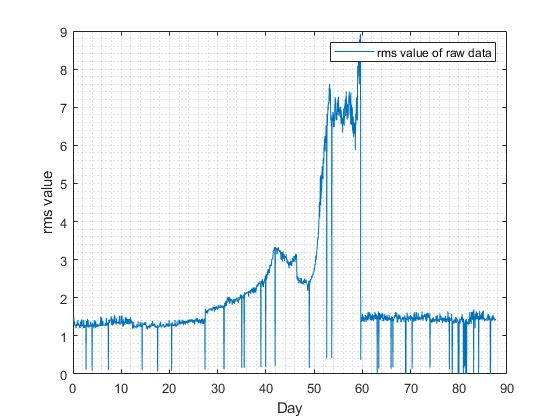

% Variables to see the result for 87days
Size = width(bearingFulldata);
perDay = 24;
idxDay = (1:Size)/perDay;

rmsRaw = rms(bearingFulldata(:,1:Size));

figure();
plot(idxDay, rmsRaw);
xlabel("Day");      ylabel("rms value");        grid minor;     legend("rms value of raw data");

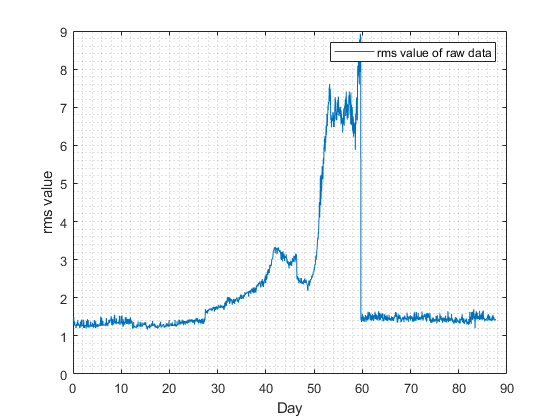

rmsUnder = find(rmsRaw < 0.5);

for Idx = 1 : length(rmsUnder)
    
  bearingFulldata(:,rmsUnder(Idx)) = bearingFulldata(:,rmsUnder(Idx)-1);
end

rmsProcess = rms(bearingFulldata(:,1:Size));

figure();
plot(idxDay, rmsProcess);       
xlabel("Day");      ylabel("rms value");        grid minor;     legend("rms value of raw data");
ylim([0 9]);

## **Feature Extraction and Analysis**

- All other time-domain features also need to be tested in the same way that the trend was identified with the rms value above.

- In order to reliably analyze the life tendency of bearings, it is important to select features that show a clear difference in tendency before and after repair, such as the rms value above.

- As we can see in the figure below, some features in time domain and frequency domain (std, rms. sra, peak ... & fc, rmsf, rvf) shows good performance to distinguish.

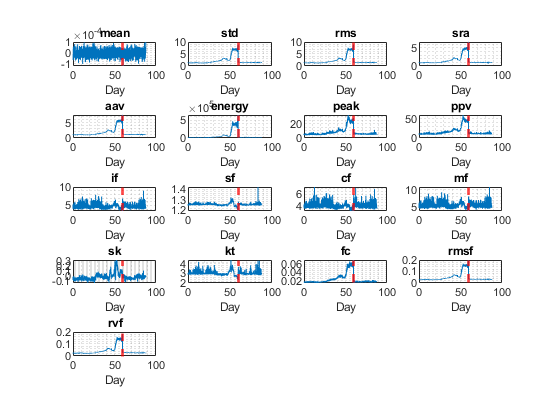

featureName = ["mean", "std", "rms", "sra", "aav", "energy", "peak", "ppv", "if", "sf", "cf", "mf", "sk", "kt", "fc", "rmsf", "rvf"];

timeFeatures = getTimefeatures(bearingFulldata);
freqFeatures = getFreqfeatures(bearingFulldata, fs);
staticFeatures = [timeFeatures freqFeatures];
staticFeatures = table2array(staticFeatures);

timeFeatures = timeFeatures(:, {'std', 'rms', 'sra', 'ppv', 'if', 'sf', 'cf', 'mf', 'sk', 'kt'});

figure()

for Idx = 1 : width(staticFeatures)
    
   subplot(5,4,Idx)
   plot(idxDay', staticFeatures(:,Idx));
   xlabel("Day");    title(featureName(Idx));   grid minor;
   xline(idxRepair/perDay, 'r--', Linewidth = 2);
end

## FFT of each cases

- Normal time     :     1

- Largest fault     :     day 59 * 24

- Repair              :     day 60 * 24

- As we can see in the FFT result of each case (normal, largest cracked, repaired) in same scale (y limit), Day 59 (largest cracked) has the large magnitude of multiple frequency components.

- To see the variation of frequency components according to the time, it is efficient to get the STFT result in the next step.

- Usually, frequency components those are from faults are usually in the range of [100 200] Hz (BPFO, BPFI). 

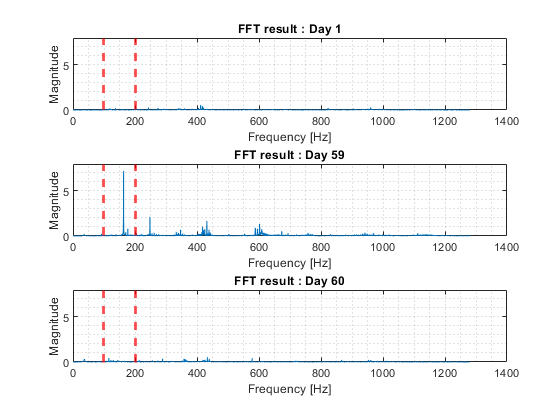

normalIdx = 1;
faultIdx  = 59 * 24;
repairIDX    = 60 * 24;

for Idx = 1 : width(bearingFulldata)
        
    [freq, mag] = getFFT(bearingFulldata(:,Idx),L, fs);
    
    if(Idx == normalIdx)
        
        subplot(3,1,1);
        plot(freq, mag);
        xline(100, 'r--', Linewidth = 2);      xline(200, 'r--', Linewidth = 2);
        xlabel("Frequency [Hz]");   ylabel("Magnitude");    grid minor;     title("FFT result : Day 1");    ylim([0 8]);
    end

    if(Idx == faultIdx)
        
        subplot(3,1,2);
        plot(freq, mag);
        xline(100, 'r--', Linewidth = 2);      xline(200, 'r--', Linewidth = 2);
        xlabel("Frequency [Hz]");   ylabel("Magnitude");    grid minor;     title("FFT result : Day 59");   ylim([0 8]);
    end

    if(Idx == repairIDX)
        
        subplot(3,1,3);
        plot(freq, mag);
        xline(100, 'r--', Linewidth = 2);      xline(200, 'r--', Linewidth = 2);
        xlabel("Frequency [Hz]");   ylabel("Magnitude");    grid minor;     title("FFT result : Day 60");   ylim([0 8]);
    end

end

## Narrowband feature

- 150 - 190 [Hz] : frequency related to bearing fault frequency

- Process of extracting narrowband feature 

- 1)    Apply FFT for everyday signal

- 2)    Extract indidces those are contained in the bandwidth (150 - 190 [Hz]) 

- 3)    Various features such as rms, rmsf, and rvf for the magnitude components of the frequency corresponding to the bandwidth were calculated.

- 4)    As figure below in this block, three narrow band feartures show good performance and the following monotocity would be good.

% nDays = width(bearingFulldata); 
% nbFeatures = zeros(nDays,3);
% 
% for day = 1 : nDays
%     
%     [freq, mag] = getFFT(bearingFulldata(:,day),L, fs);
%     N = length(mag);
% 
%     narrowIdx = find(freq >= 150 & freq <= 190);
% 
%     narrowMag = mag(narrowIdx);
%     
%     nbCenterFreq = sum(narrowMag)/N;
%     nbRmsf = sqrt(sum(narrowMag.^2)/N);
%     nbRvf = sqrt(sum((narrowMag - nbCenterFreq).^2)/N);
% 
%     nbFeatures(day, 1) = nbCenterFreq;
%     nbFeatures(day, 2) = nbRmsf;
%     nbFeatures(day, 3) = nbRvf;
% end
% 
% nbVariableName = ["nbCF", "nbRMSF", "nbRVF"];
% nbFeaturesDay = nbFeatures(1:perDay:length(idxDay),: );
% nbFeaturesDay = array2table(nbFeaturesDay, 'VariableNames', nbVariableName)
% figure
% subplot(3,1,1)
% plot(idxDay, nbFeatures(:,1));
% xline(60,'r--','LineWidth',2);
% xlabel('day');      ylabel('cf');   grid minor;
% title('narrow band : center frequency');
% 
% subplot(3,1,2)
% plot(idxDay,nbFeatures(:,2));
% xline(60,'r--','LineWidth',2);
% xlabel('day');      ylabel('rmsf');    grid minor;
% title('narrow band std value'); 
% title('narrow band : rmsf');
% 
% subplot(3,1,3)
% plot(idxDay,nbFeatures(:,3));
% xline(60,'r--','LineWidth',2);
% xlabel('day');      ylabel('rvf');    grid minor;
% title('narrow band std value'); 
% title('narrow band : rvf');

## **Spectral kurtosis**

- As figure above shows, spectral kurtosis has a poor monotocity.

- Spectral kurtosis over time can be analyzed.

wc = 128;
Index = 1;

rawData = [bearing bearingNew];

% ----- Which data to see ? -----
% 1 : raw data
% 2 : processed data

selectData = 2

selectData = 2

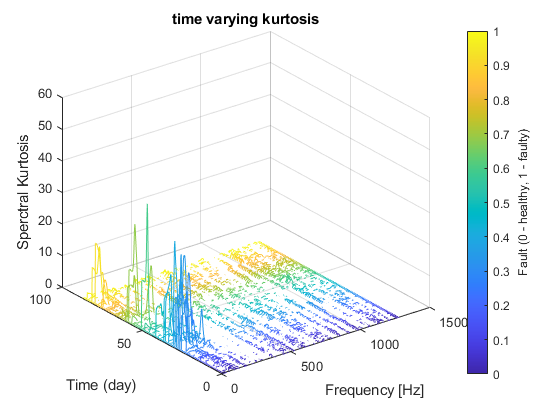

switch selectData

    case 1
        dataToanalyze = rawData;            % rawdata
    case 2
        dataToanalyze = bearingFulldata;    % preprocessed data
end

colors = parula(width(dataToanalyze));

figure()

for Idx = 1 : perDay : width(dataToanalyze)

    kurtosisDat = table();

    [kurtosisSK, kurtosisF] = pkurtosis(dataToanalyze(:,Idx), fs, wc);
    
    kurtosis_sk(:,Index) = kurtosisSK;

    kurtosisDat.SpectralKurtosis = {table(kurtosisF, kurtosisSK)};
    plot3(kurtosisF, (Idx * ones(size(kurtosisF)))/perDay, kurtosisSK, 'Color', colors(Idx, :));
    zlim([0 60]);   grid on;    hold on;

    Index = Index + 1;
end

xlabel("Frequency [Hz]");   ylabel("Time (day)");    zlabel("Sperctral Kurtosis");
cbar = colorbar;    ylabel(cbar, 'Fault (0 - healthy, 1 - faulty)');     title('time varying kurtosis');

kurtosisResult = struct('mean',     mean(kurtosis_sk),     ...
                        'std',      std(kurtosis_sk),      ...
                        'skewness', skewness(kurtosis_sk), ...
                        'kurtosis', kurtosis(kurtosis_sk));

skFeature = [kurtosisResult.mean' kurtosisResult.std' kurtosisResult.skewness' kurtosisResult.kurtosis'];

skName = ["skMean", "skStd", "skSkewness", "skKurtosis"];
skFeature = array2table(skFeature, "VariableNames",skName);

## **Selection of Features**

- In order to prepare the training data, data until normal operation by repair is required , and processing is performed accordingly.

- Variable 'allFeatureTbl' shows the data explained above.

timeFeaturesDay = timeFeatures(1 : perDay : length(idxDay),: );
freqFeaturesDay = freqFeatures(1 : perDay : length(idxDay),: );

% Shows all features of the period
% allFeatureTbl = [table2array(timeFeaturesDay(2:60,: ))      table2array(freqFeaturesDay(2:60,: ))      table2array(skFeature(2:60, :))      table2array(nbFeaturesDay(2:60, :))];
allFeatureTbl = [table2array(timeFeaturesDay(1:59,: ))      table2array(freqFeaturesDay(1:59,: ))      table2array(skFeature(1:59, :)) ];

tbltimeFeatureName = ["std", "rms", "sra", "ppv", "if", "sf", "cf", "mf", "sk", "kt", "center freq", "rmsf", "rvf"] ;    % 10개 

% tableLabel = [tbltimeFeatureName  skName  nbVariableName];
tableLabel = [tbltimeFeatureName  skName ];

dateReal = (datetime(2021,4,13) : days(1) : datetime(2021,7,11));
dateTime = (dateReal(2:60)); 


allFeatureTbl = array2table(allFeatureTbl, "VariableNames", tableLabel);
allFeatureTbl = table2timetable(allFeatureTbl, 'RowTimes', dateTime)

allFeatureTbl = 59×17 timetable
       Time        std       rms        sra       ppv       if        sf        cf        mf          sk          kt      center freq      rmsf        rvf        skMean      skStd     skSkewness    skKurtosis
    __________    ______    ______    _______    _____    ______    ______    ______    ______    __________    ______    ___________    ________    ________    ________    _______ 

## Feature postprocessing

- Since data without filtering contains noise, it needs to be filtered using median filter for smoothing. 

- Result of filtering will be used for training.

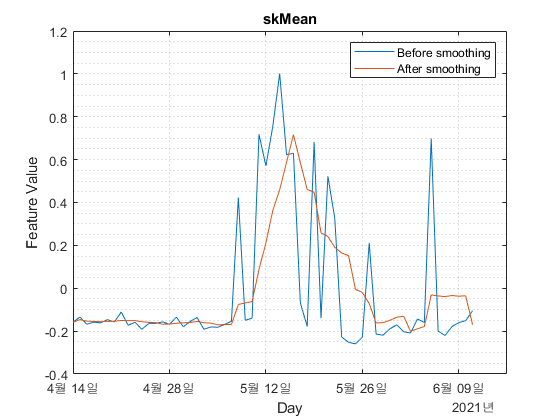

variableNames = allFeatureTbl.Properties.VariableNames;
featureTableSmooth = varfun(@(x) movmean(x, [5 0]), allFeatureTbl); 
featureTableSmooth.Properties.VariableNames = variableNames;

featureValues = zeros(1, 59);

figure

plot(allFeatureTbl.Time, allFeatureTbl.skMean);
hold on;
plot(allFeatureTbl.Time, featureTableSmooth.skMean);
hold off;  
xlabel("Day");  ylabel("Feature Value");    legend('Before smoothing', 'After smoothing');  grid minor;
title("skMean");

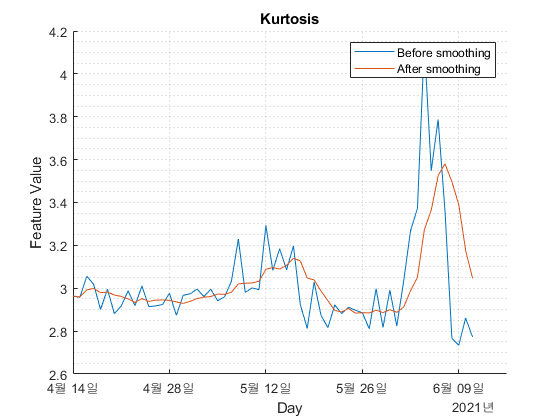

figure
hold on
plot(allFeatureTbl.Time, allFeatureTbl.kt);
plot(allFeatureTbl.Time, featureTableSmooth.kt)
hold off
xlabel("Day");  ylabel("Feature Value");    legend('Before smoothing', 'After smoothing');  grid minor;
title("Kurtosis");

## Training

- breakpoing : index 42 was selected for preparing data sets

- This breakpoint allows about 50 percent of date index (42/89) to be trained.

% About 50% selection for trianing
breaktimeFirst = datetime(2021, 4,29);
breaktime      = datetime(2021, 5, 26);

breakpoint = find(featureTableSmooth.Time < breaktime , 1, 'last');  

trainData  = featureTableSmooth(1:breakpoint, :)

trainData = 42×17 timetable
       Time        std       rms        sra       ppv        if        sf        cf        mf         sk          kt      center freq      rmsf        rvf        skMean      skStd     skSkewness    skKurtosis
    __________    ______    ______    _______    ______    ______    ______    ______    ______    _________    ______    ___________    ________    ________    ________    _______    <

## Feature importance ranking

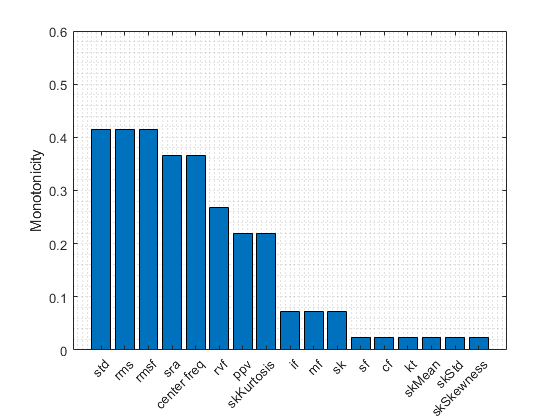

% Since moving window smoothing is already done, set 'WindowSize' to 0
% turn off the smoothing within the function
featureImportance = monotonicity(trainData, 'WindowSize', 0);
helperSortedBarPlot(featureImportance, 'Monotonicity');
ylim([0 0.6]);      grid minor;

- Making new dataset composed of selected features.

trainIdx = featureImportance{:,:} > 0.4;

trainDataSelected = trainData(:, trainIdx);
featureSelected = featureTableSmooth(:, trainIdx)

featureSelected = 59×3 timetable
       Time        std       rms        rmsf  
    __________    ______    ______    ________

    2021-04-14    1.3984    1.3983    0.030895
    2021-04-15     1.339    1.3389    0.029583
    2021-04-16    1.3227    1.3226    0.029223
    2021-04-17    1.3266    1.3265    0.029308
    2021-04-18    1.3305    1.3304    0.029395
    2021-04-19     1.327    1.3269    0.029317
    2021-04-20    1.3047    1.3046    0.028824
    2021-04-21    1.3076    1.3075    0.028889
    2021-04-22    1.3083    1.3082    0.028904
    2021-04-23    1.3107    1.3106    0.028958
    2021-04-24    1.3104    1.3103    0.028951
    2021-04-25 

## Dimension reduction & feature fusion

- Data normalization

- Apply principal component analysis with normalized datasets.(proprocessing for PCA)

meanTrain = mean(trainDataSelected{:,:});
sdTrain = std(trainDataSelected{:,:});
trainDataNormalized = (trainDataSelected{:,:} - meanTrain)./sdTrain;

% principal component vector
coef = pca(trainDataNormalized);

% PCA : 원본데이터가 PCA1, PCA2 주성분에 projection된 결과
% 이 값들은 원본 데이터의 차원을 축소한 결과로, 주요 패턴과 상관관계를 표현하기에 적합
PCA1 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
PCA2 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

timeUnit = 'day';

- visualizing

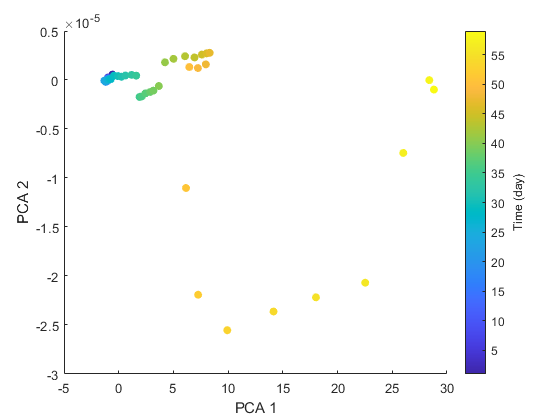

figure
numData = size(featureTableSmooth, 1);
scatter(PCA1, PCA2, [], 1:numData, 'filled');
xlabel('PCA 1');
ylabel('PCA 2');
cbar = colorbar;
ylabel(cbar, ['Time (' timeUnit ')']);

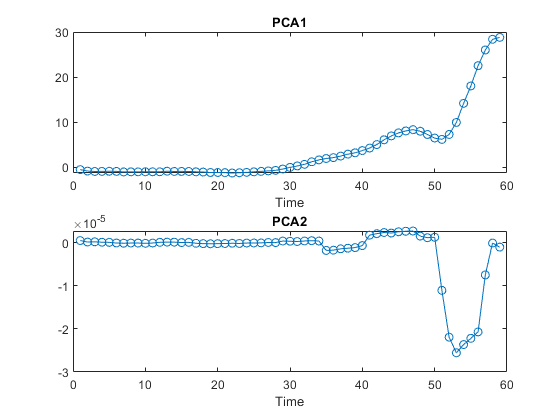

figure
subplot(2,1,1)
plot(PCA1, '-o')
xlabel('Time')
title('PCA1')

subplot(2,1,2)
plot(PCA2, '-o')
xlabel('Time')
title('PCA2')

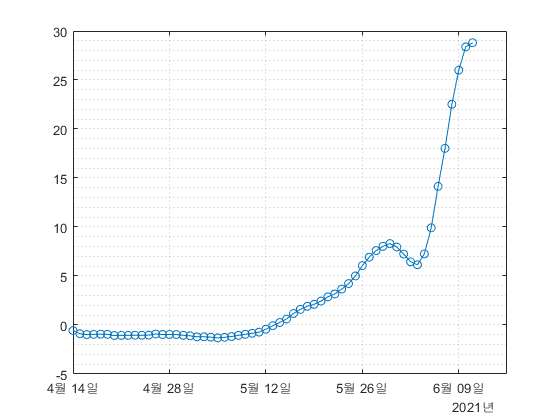

figure
healthIndicator = PCA1;

plot(featureSelected.Time, healthIndicator, '-o');
grid minor;

## Fault Monitoring and Warning

#### RUL based on exponential degradation model

- pdf of RUL : probability density funtion of RUL, which represents the probability distribution of the predicted RUL values. Through this, uncertainty of RUL can be checked and range of possible RUL values can be estimated.

- `Estimated RUL`: The remaining useful life value predicted using the model. This value predicts how much life is left in the bearing, which helps in planning maintenance and replacements.

- `True RUL `: The actual Remaining Useful Life value, which is the real remaining life of the bearing. It is used to compare with the estimated RUL to evaluate the model's performance.

- `Confidence interval`: A range of values within which the true RUL is likely to fall with a certain level of confidence. It provides an indication of the uncertainty associated with the RUL estimation.

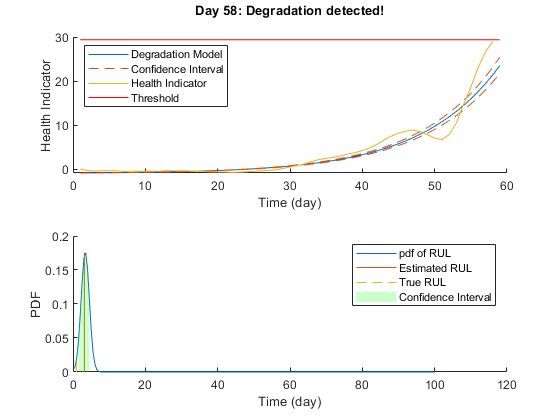

healthIndicator = healthIndicator - healthIndicator(1);
threshold = healthIndicator(end);


mdl = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold/(threshold + 1))^2, ...
    'SlopeDetectionLevel', 0.05);


% Keep records at each iteration
totalDay = length(healthIndicator) - 1;
estRULs = zeros(totalDay, 1);
trueRULs = zeros(totalDay, 1);
CIRULs = zeros(totalDay, 2);
pdfRULs = cell(totalDay, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

for currentDay = 1:totalDay
    
    % Update model parameter posterior distribution
    update(mdl, [currentDay healthIndicator(currentDay)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                                         [currentDay healthIndicator(currentDay)], ...
                                         threshold);
    trueRUL = totalDay - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator, mdl, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    estRULs(currentDay) = estRUL;
    trueRULs(currentDay) = trueRUL;
    CIRULs(currentDay, :) = CIRUL;
    pdfRULs{currentDay} = pdfRUL;
    
    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

## RUL Estimation

- Explained in the 'discussion'

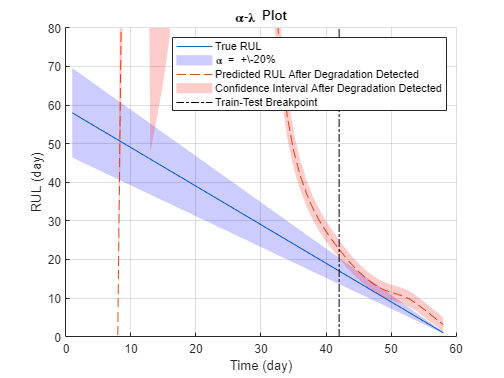

alpha = 0.2;
detectTime = mdl.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs, estRULs, CIRULs, ...
    pdfRULs, detectTime, breakpoint, timeUnit);
title('\alpha-\lambda Plot');

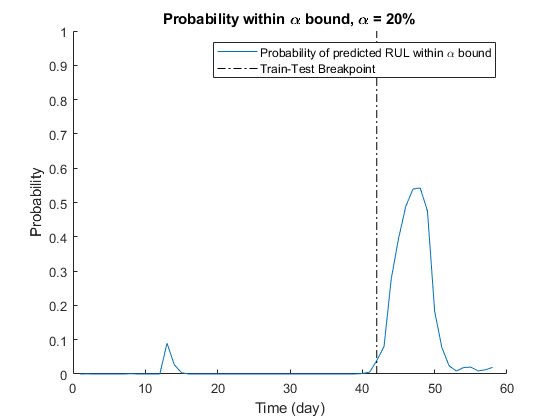

figure
t = 1:totalDay;
hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])

## Discussion 

1) Data analysis

        The experimental data was measured a total of 24 times per day for approximately 87 days. The measurements from day 1 to day 59 represent the operation before maintenance, and those from day 60 onwards represent the measurements after maintenance. As observed from the characteristics in the time domain and frequency domain, as well as the FFT results and spectral kurtosis, there is a clear difference between the measurements before and after maintenance. There are some parts where the bearing does not rotate intermittently, causing the values to appear to jump. To address this, I performed preprocessing to refer to the previous value for those sections. Additionally, for the future task of predicting RUL, it is essential to select features that clearly distinguish the measurements before and after maintenance. There are many features available, such as std, rms, sra, aav, fc, rmsf, rvf, among others.

2) Narrow band anlaysis

       In this study, to extract features with higher monotonicity, we performed a Fourier Transform (FFT) analysis on the narrowband signals within the frequency range of 150-190Hz, where bearing faults are primarily observed. Features such as center frequency, rmsf, and rvf for the corresponding frequency band were computed. As a result, it was able to extract features with better monotonicity performance compared to the various time and frequency features previously obtained.

3) PCA & dimension reduction 

      The appearance of a graph showing a linearly increasing trend indicates a positive correlation between PCA1 and PCA2. This implies that the selected primary features exhibit a consistent relationship and change over time. These findings indicate that PCA effectively captures the main patterns, which can aid in predicting changes in bearing status or failure progression. Based on these results, it is possible to confirm that the primary features are changing in a consistent direction over time. This information can be used to develop a prediction model for estimating bearing Remaining Useful Life (RUL) or exploring other correlations within the system.

4) Fault monitoring & RUL estimation

      The data before the Train-Test Breakpoint is used for model training. However, if at this point, the True RUL (Remaining Useful Life) and the prediction do not match completely, it may indicate that the model has not fully learned the patterns in the data. This is a common phenomenon that occurs during the training process, as the model gradually accumulates information about the data, resulting in improved prediction performance.

At this point, low prediction accuracy does not necessarily mean that the model is inadequate. On the contrary, it provides an opportunity to observe the model's learning process and evaluate its performance. Therefore, prediction errors at this stage can be considered as part of the model's learning and improvement process.

However, if the prediction accuracy continues to be low in the training data, it may indicate that the model is not fitting well or is underfitting. In this case, the model may need to be improved or a different model may need to be used. To address such issues, methods such as adjusting the model's hyperparameters, using different algorithms, or collecting additional data can be employed.